In the first problem of this homework assignment a Radial Basis Function neural network will be trained on MNIST dataset and its classification performance will be reported.

The second problem discussed how to find the partial derivatives to be used on gradient descent algorithm.

clc; clear; close all;
load('HW12_code_workspace.mat');

# MNIST Dataset

## 0.1 Downloading MNIST Dataset and Import into *Matlab*

The code snippet below will download MNIST dataset from web and extract the downloaded files into Matlab matrices as test and train images and labels.

mnist_train_image = 'train-images-idx3-ubyte';
mnist_train_label = 'train-labels-idx1-ubyte';
mnist_test_image  = 't10k-images-idx3-ubyte';
mnist_test_label  = 't10k-labels-idx1-ubyte';
train_set_number  = 60000;
test_set_number   = 10000;

downloadMNIST(mnist_train_image, mnist_train_label, mnist_test_image, mnist_test_label);

MNIST dataset downloded.
Unzipping started...
Unzipping completed.


[train_images, train_labels] = readMNIST(mnist_train_image, mnist_train_label, train_set_number);
[test_images,   test_labels] = readMNIST(mnist_test_image, mnist_test_label, test_set_number);

clear mnist_train_image mnist_train_label mnist_test_image mnist_test_label train_set_number test_set_number

## 0.2 Plotting a Sample of MNIST Dataset

A set of 100 randomly chosen samples of the training dataset is plotted here.

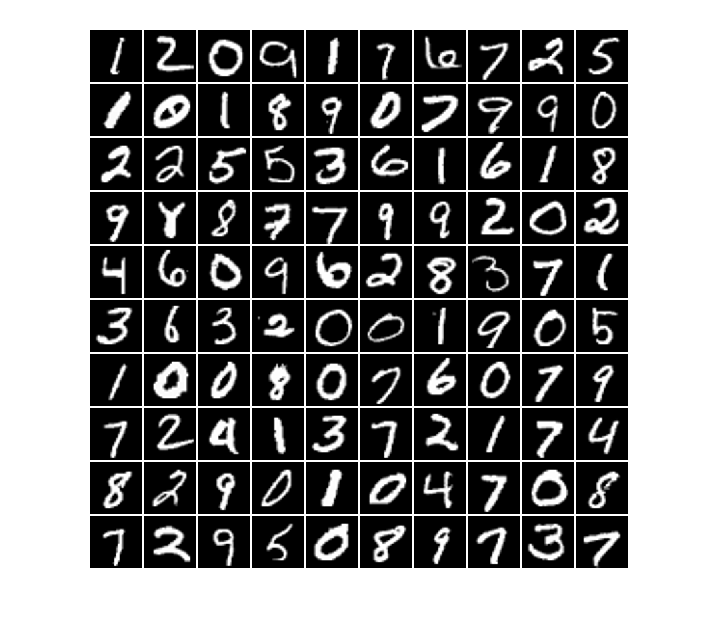

random_indices = randi(60000, [1 100]);
montage(train_images(:, :, random_indices), 'BorderSize', [2 2], 'BackgroundColor', 'white');

## 0.3 Number of Occurances for Each Digit in Training Set

Here we investigate how many of each digit is there in the training set.

for i=0:9
    disp([num2str(i),': ', num2str(sum(train_labels == i))]);
end

0: 5923
1: 6742
2: 5958
3: 6131
4: 5842
5: 5421
6: 5918
7: 6265
8: 5851
9: 5949


## 0.4 Rashaping Images Into Vectors

For further calculations it is more desirable to work with vectors of 784 elements instead of 28x28 size images.

train_images_reshaped = reshape(train_images, [size(train_images, 1)*size(train_images, 2) size(train_images, 3)]);
test_images_reshaped = reshape(test_images, [size(test_images, 1)*size(test_images, 2) size(test_images, 3)]);

# Problem 1

In this problem we implement an RBF network with 40 hidden units and 10 binary outputs.

## 1.1 Finding Centroids Using K-means Clustring Algorithm

By running a K-means algorithm on the training dataset, we have found 40 centroids to be used later in the radial basis functions.

K = 40;
[idx, centroids] = kmeans(train_images_reshaped', K, "Display", "iter", "MaxIter", 1000, 'OnlinePhase','on');

  iter	 phase	     num	         sum
     1	     1	   60000	 2.17743e+06
     2	     1	   17400	 2.03712e+06
     3	     1	    8921	 1.99709e+06
     4	     1	    5806	 1.97847e+06
     5	     1	    4445	 1.96579e+06
     6	     1	    3544	 1.95701e+06
     7	     1	    2930	 1.95091e+06
     8	     1	    2449	 1.94653e+06
     9	     1	    2030	 1.94354e+06
    10	     1	    1667	  1.9415e+06
    11	     1	    1454	 1.93993e+06
    12	     1	    1216	 1.93875e+06
    13	     1	    1124	 1.93772e+06
    14	     1	    1058	  1.9368e+06
    15	     1	     960	 1.93605e+06
    16	     1	     933	 1.93534e+06
    17	     1	     853	 1.93469e+06
    18	     1	     884	 1.93397e+06
    19	     1	     893	 1.93322e+06
    20	     1	     919	 1.93239e+06
    21	     1	     947	 1.93141e+06
    22	     1	     949	 1.93028e+06
    23	     1	    1020	  1.9288e+06
    24	     1	    1066	   1.927e+06
    25	     1	     998	 1.92553e+06
    26	     1	     908	 1.92448e+06
    27	     1	     863	 1.92

The 40 centroids are plotted below:

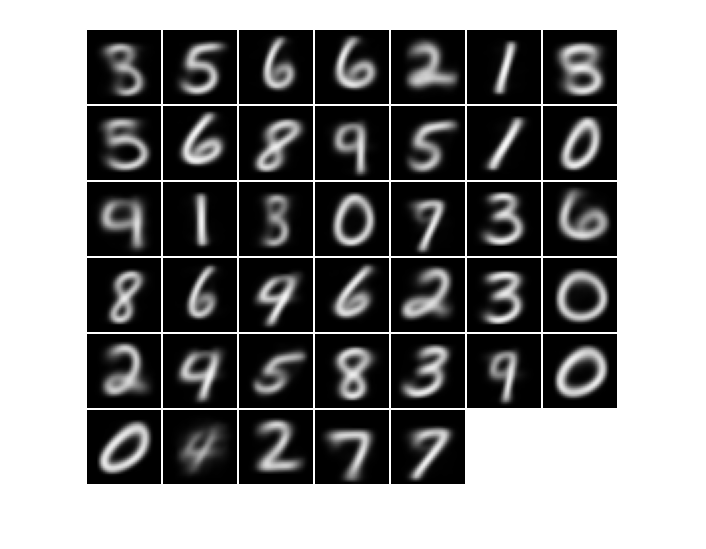

iMontage(centroids');

The 2 line codes below will change the labels into a one-hot-encoded matrix.

train_labels_one_hot_encoded = full(ind2vec(train_labels'+1));
test_labels_one_hot_encoded  = full(ind2vec(test_labels'+1));

## 1.2 Finding Weights Using Psuedo-Inverse

We first find the matrix of th radial basis functions' outputs and then by using the psuedo-inverse of it, the weights will be known as the equation below:

 
$$\mathbf{W = \Phi^\dagger y}$$


sigma = max(max(dist(centroids)))/sqrt(2*K);
N = size(train_images_reshaped, 2);
hidden = zeros(N, K);

for i = 1:40
    hidden(:, i) = exp(vecnorm(train_images_reshaped'-centroids(i, :), 2, 2).^2/(-2*sigma*sigma));
end

weights = (inv(hidden'*hidden) * hidden') * (train_labels_one_hot_encoded');

With the code snippet below, we first predict the labels of training dataset with the RBF network, then plot the confusion matrix to see how is the classification performance. 

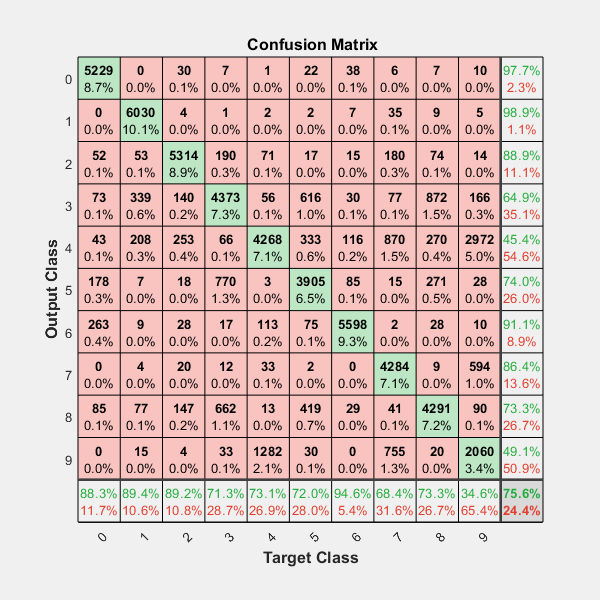

predicted_train_labels_one_hot_encoded = hidden * weights;

[~, train_labels_predicted] = max(predicted_train_labels_one_hot_encoded');

categorized_label_train = categorical(train_labels, 0:9, {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9'});
categorized_label_train_predicted = categorical(train_labels_predicted', 1:10, {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9'});

plotconfusion(categorized_label_train, categorized_label_train_predicted);

## 1.3 Plotting Learning Curves

By using psuedo-inverse algorithm we have found the weights at once, so there is no learning curve available to be displayed.

## 1.4 Classification Performance

With the code snippet below, we first predict the labels of test dataset with the RBF network, then plot the confusion matrix to see how is the classification performance. 

As it is clear, performance on the whole test set of MNIST is about 76% which is acceptable in comparison with the time that feed forward neural networks need to be trained and acheive a comparable performance. 

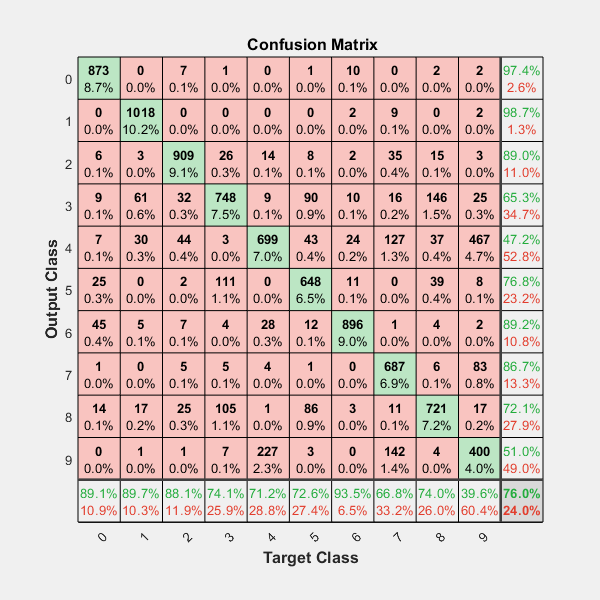

N_test = size(test_images_reshaped, 2);
hidden_test = zeros(N_test, K);

for i = 1:40
    hidden_test(:, i) = exp(vecnorm(test_images_reshaped'-centroids(i, :), 2, 2).^2/(-2*sigma*sigma));
end

predicted_test_labels_one_hot_encoded = hidden_test*weights;

[~, I] = max(predicted_test_labels_one_hot_encoded');

categorized_label_test = categorical(test_labels, 0:9, {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9'});
categorized_label_test_predicted = categorical(I', 1:10, {'0' '1' '2' '3' '4' '5' '6' '7' '8' '9'});

plotconfusion(categorized_label_test, categorized_label_test_predicted);

# Problem 2

# Appendix

## A.1 Saving Workspace Variables for Future Use 

save('HW12_code_workspace.mat');

## A.2 Definition of Auxiliary Functions

function downloadMNIST(mnist_train_image, mnist_train_label, mnist_test_image, mnist_test_label)

if exist('train-images-idx3-ubyte','file') ~= 2
    disp('Downloading MNIST dataset...');
    websave([mnist_train_image,'.gz'],...
        ['http://yann.lecun.com/exdb/mnist/', ...
        mnist_train_image, '.gz']);
    websave([mnist_train_label,'.gz'],...
        ['http://yann.lecun.com/exdb/mnist/', ...
        mnist_train_label, '.gz']);
    websave([mnist_test_image,'.gz'],...    
        ['http://yann.lecun.com/exdb/mnist/', ...
        mnist_test_image, '.gz']);
    websave([mnist_test_label,'.gz'],...
        ['http://yann.lecun.com/exdb/mnist/', ...
        mnist_test_label, '.gz']);
    disp('MNIST dataset downloded.');
    
    disp('Unzipping started...');
    gunzip([mnist_train_image, '.gz'])
    gunzip([mnist_train_label, '.gz'])
    gunzip([mnist_test_image, '.gz'])
    gunzip([mnist_test_label, '.gz'])
    delete([mnist_train_image, '.gz'])
    delete([mnist_train_label, '.gz'])
    delete([mnist_test_image, '.gz'])
    delete([mnist_test_label, '.gz'])
    disp('Unzipping completed.');
else
    disp('MNIST dataset already downloaded.')
end

end

function [imgs, labels] = readMNIST(imgFile, labelFile, num_of_digits_to_read)

fileID = fopen(imgFile, 'r', 'b');
header = fread(fileID, 1, 'int32');

if header ~= 2051
    error('Invalid image file header');
end

count = fread(fileID, 1, 'int32');

if count < num_of_digits_to_read
    error('Trying to read too many digits');
end

rows_num = fread(fileID, 1, 'int32');
cols_num = fread(fileID, 1, 'int32');

imgs = zeros([rows_num cols_num num_of_digits_to_read]);

for i = 1:num_of_digits_to_read
    for row = 1:rows_num
        imgs(row, :, i) = fread(fileID, cols_num, 'uint8');
    end
end

fclose(fileID);

fileID = fopen(labelFile, 'r', 'b');
header = fread(fileID, 1, 'int32');

if header ~= 2049
    error('Invalid label file header');
end

count = fread(fileID, 1, 'int32');

if count < num_of_digits_to_read
    error('Trying to read too many digits');
end

labels = fread(fileID, num_of_digits_to_read, 'uint8');

fclose(fileID);

imgs = double(imgs)./255.0;

end

function iMontage(images)
montage(reshape(images, [28 28 size(images, 2)]), 'BackgroundColor', 'white', 'BorderSize', [2 2]);
end